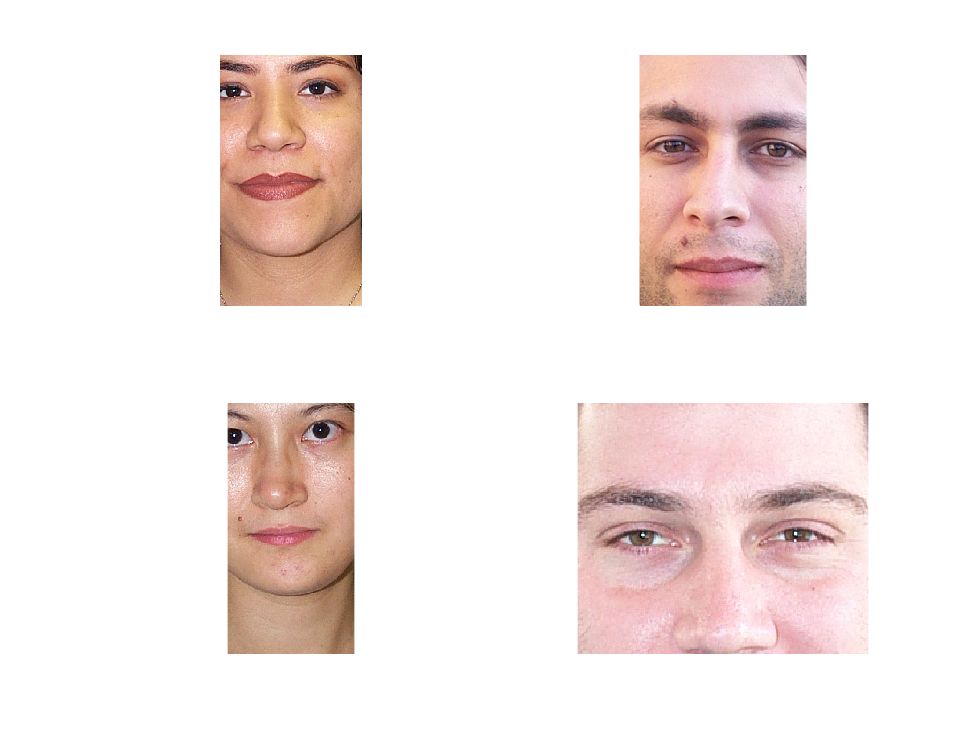

folder = "skin"; %%locate folder
imagefiles = dir(fullfile(folder,'*.png')); %%store the images
nfiles = length(imagefiles); %%define number of images.
Im = cell(1,nfiles); %%Allocate space

%%for each image
for i = 1:nfiles
  filename=fullfile(folder,imagefiles(i).name); %%get filename of current image.
  subplot(nfiles/2, nfiles/2, i); %%define location to plot the image in our subplot.
  Im{i}=im2double(imread(filename)); %%Read the imagefile, convert to double and store it.
  imshow(Im{i}) %%Show the current image in a subplot.
end

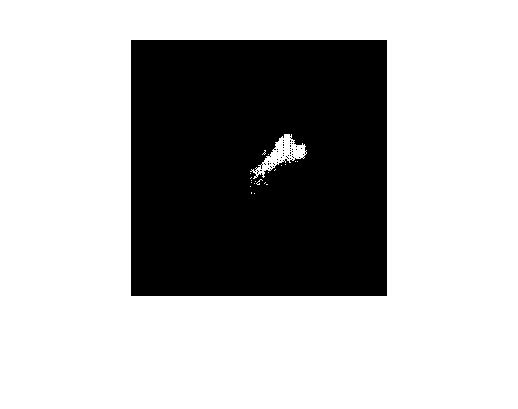

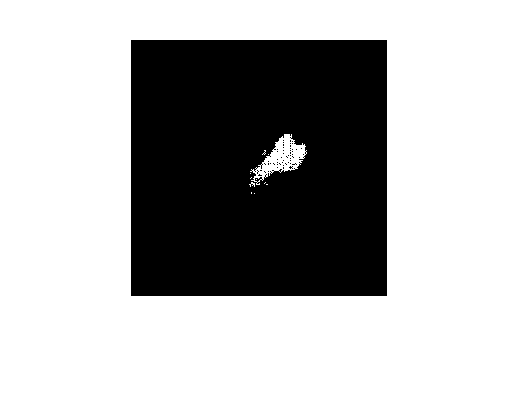

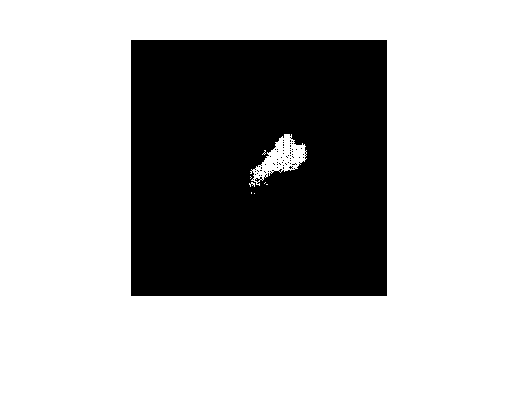

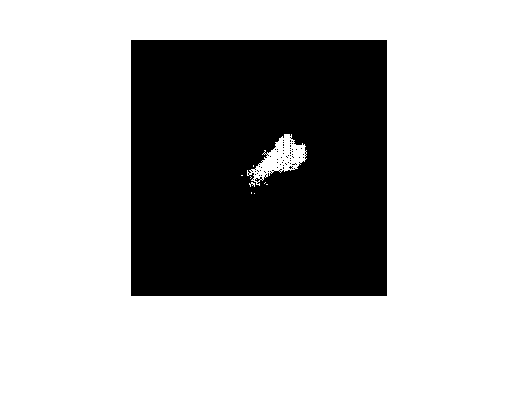



prob_image = zeros(256);

for i = 1:nfiles
  YCbCr = rgb2ycbcr(Im{i}); %%convert the first image in our folder to YCbCr.
  [Y, Cb, Cr] = imsplit(YCbCr); %%split the image into Y, Cb and Cr.'
  
  arrayCb = Cb';
  arrayCb = arrayCb(:)';
  arrayCr = Cr';
  arrayCr = arrayCr(:)';

  
  for k = 1:numel(arrayCr)
      
      prob_image(round(arrayCb(k)*255), round(arrayCr(k)*255)) =+ 1;
  end
  
  prob_image = prob_image./max(prob_image(:));
  figure;
  imshow(prob_image)
  
  
end


imwrite(prob_image, "skinprobability.png")

